load("spikes.mat")
meann = mean(spikes);
sd = std(spikes);

spikes_norm = (spikes-meann)./sd;
[w,u ,lambda]= pca(spikes_norm);
Data = u(:,1:2);
x = linspace(1,length(Data),length(Data)/3)

x = 	1.0e+04 *

    0.0001    0.0004    0.0007    0.0010    0.0013    0.0016    0.0019    0.0022    0.0025    0.0028    0.0031    0.0034    0.0037    0.0040    0.0043    0.0046    0.0049    0.0052    0.0055    0.0058    0.0061    0.0064    0.0067    0.0070    0.0073    0.0076    0.0079    0.0082    0.0085    0.0088    0.0091    0.0094    0.0097    0.0100    0.0103    0.0106    0.0109    0.0112    0.0115    0.0118    0.0121    0.0124    0.0127    0.0130    0.0133    0.0136    0.0139    0.0142    0.0145    0.0148


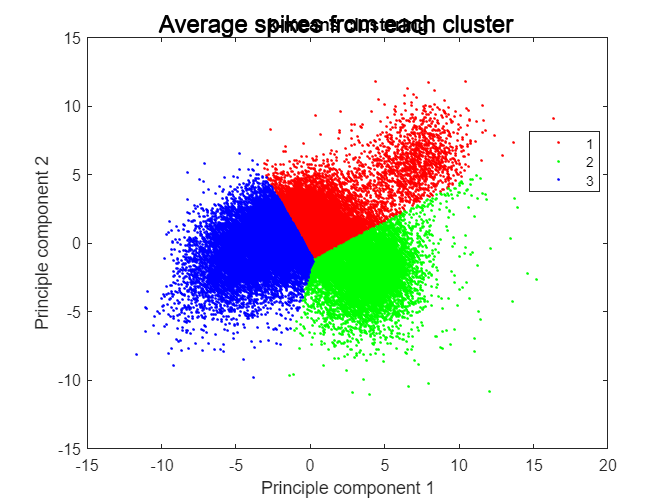


k = 3;
r = randsample(length(Data), k);
centroids = [Data(r(1), 1), Data(r(1), 2); Data(r(2), 1),Data(r(2), 2); Data(r(3), 1),Data(r(3), 2)];

t = 0;
k_key = 0;
k_key0 = 0;
g = 0;
while t == 0    
    g = g+1;
    k_key0=k_key;
    for i = [1:length(Data)]
        x = Data(i,:);

        distance = 0;
        distance(1) = pdist([x;centroids(1,:)],'euclidean');
        distance(2) = pdist([x;centroids(2,:)],'euclidean');
        distance(3) = pdist([x;centroids(3,:)],'euclidean');
%         distance(1) = sqrt((x(1)+centroids(1,1))^2+(x(2)+centroids(1,2))^2);
%         distance(2) = sqrt((x(1)+centroids(2,1))^2+(x(2)+centroids(2,2))^2);
%         distance(3) = sqrt((x(1)+centroids(3,1))^2+(x(2)+centroids(3,2))^2);
        [~,k_val] = min(distance);
        k_key(i) = k_val;
    end
    c1 = Data(k_key == 1, :);
    c2 = Data(k_key == 2, :);
    c3 = Data(k_key == 3, :);
    centroids = [mean(c1);mean(c2);mean(c3) ];
    if k_key0 == k_key
        t = 1;
    end
%     if g==10
%         t = 1;
%     end
    
end    
figure
gscatter(Data(:,1), Data(:,2), k_key)
title('k-means clustering')
xlabel("Principle component 1")
ylabel("Principle component 2")

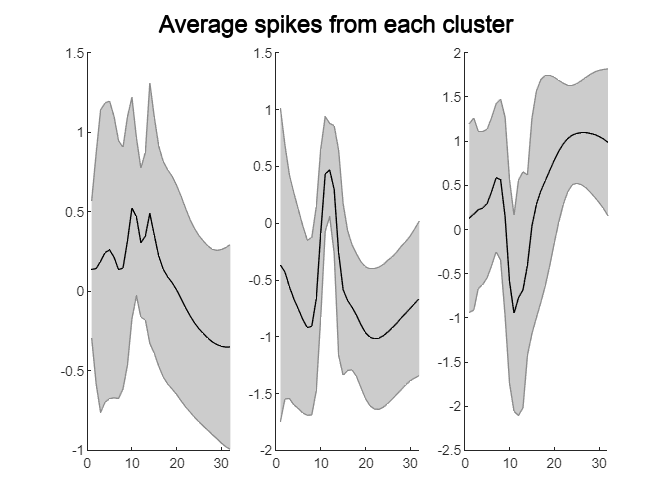

k1spikes = mean(spikes_norm(k_key==1, :));
k2spikes = mean(spikes_norm(k_key==2, :));
k3spikes = mean(spikes_norm(k_key==3, :));
figure
subplot(1,3,1)
sgtitle("Average spikes from each cluster")
shadedErrorBar([],k1spikes, std(spikes_norm(k_key==1, :)))
subplot(1,3,2)
shadedErrorBar([],k2spikes, std(spikes_norm(k_key==2, :)))
subplot(1,3,3)
shadedErrorBar([],k3spikes, std(spikes_norm(k_key==3, :)))
hold off
hold off

# Part 2


k = 3

k = 3

r = randsample(length(Data), k)

r =        23911
        2485
        9760


centroids = [Data(r(1), :); Data(r(2), :);Data(r(3), :)]

centroids =     3.9704    6.2007
    3.8056   -3.5770
   -0.8822    0.5231


t = 0;
k_key0 = 0;
k_keymed = 0;
g = 0;
while t == 0    
    g = g+1;
    k_key0=k_keymed;
    for i = [1:length(Data)]
        x = Data(i,:);

        distance = 0;
        distance(1) = pdist([x;centroids(1,:)],'euclidean');
        distance(2) = pdist([x;centroids(2,:)],'euclidean');
        distance(3) = pdist([x;centroids(3,:)],'euclidean');
        [~,k_val] = min(distance);
        k_keymed(i) = k_val;
    end
    c1 = Data(k_keymed == 1, :);
    c2 = Data(k_keymed == 2, :);
    c3 = Data(k_keymed == 3, :);
    centroids = [median(c1);median(c2);median(c3)];
    if k_key0 == k_keymed
        t = 1;
    end
%     if g==10
%         t = 1;
%     end
    
end    

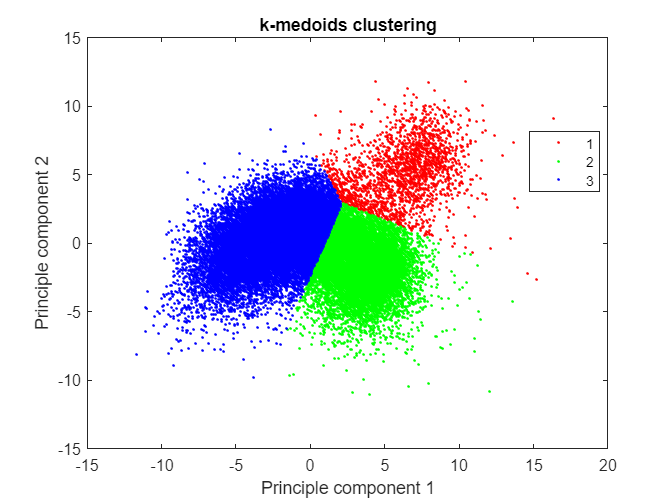


figure
gscatter(Data(:,1), Data(:,2), k_keymed)

title('k-medoids clustering')
xlabel("Principle component 1")
ylabel("Principle component 2")

k = 3

k = 3

%centroids taken from prior part
c = Data;
store_k = k_key;

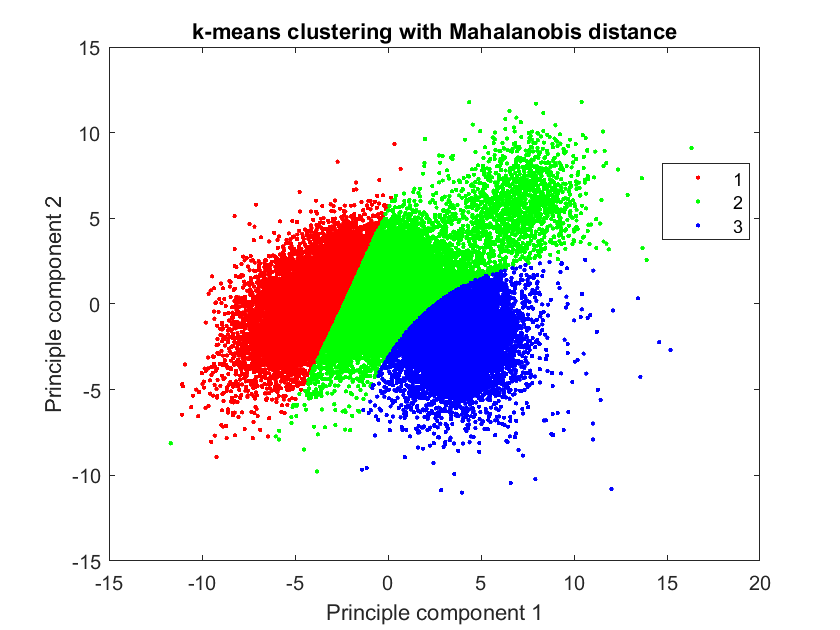

k_key = store_k;
t = 0;

g = 0;
while t == 0
    g = g+1;

    c1 = mahal(Data, Data(k_key == 1, :));
    c2 = mahal(Data, Data(k_key == 2, :));
    c3 = mahal(Data, Data(k_key == 3, :));
    c = [c1 c2 c3];
    [~,k_key] = min(c');
    if g == 5
        t = 1;
    end
end

figure
gscatter(Data(:,1), Data(:,2), k_key)
title('k-means clustering with Mahalanobis distance')
xlabel("Principle component 1")
ylabel("Principle component 2")

# Part 3

K = 3;
X = Data;
options	=	statset('display','final');
obj	=	gmdistribution.fit(X,K,'options',options);

86 iterations, log-likelihood = -198220


clusters	=	cluster(obj,X);
figure

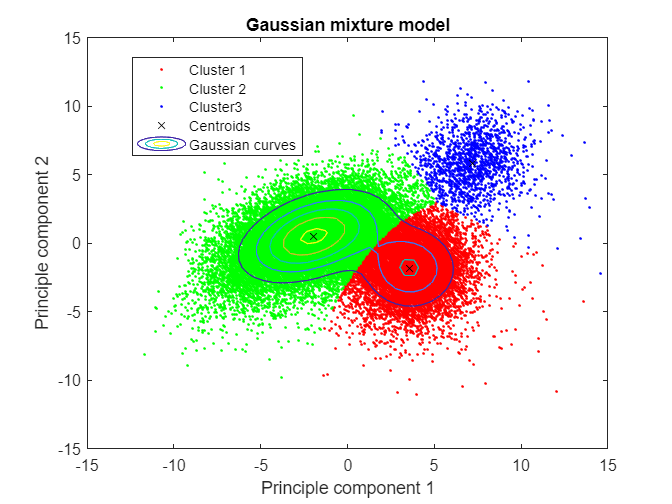

figure
gscatter(Data(:,1),Data(:,2),clusters)
hold on
centroids	=	obj.mu;
plot(centroids(:,1), centroids(:,2), 'kx')
h	=	ezcontour(@(x,y)pdf(obj,[x	y]),[-15	15],[-15	15]);

legend('Cluster 1', 'Cluster 2', "Cluster3", 'Centroids', "Gaussian curves")
title("Gaussian mixture model")
xlabel("Principle component 1")
ylabel("Principle component 2")
hold off